# SBT_CW.mat Data Cleaning

Simple Box Test, Clock Wise

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 12; % Time spent sitting still before test for initialization

% Load Raw Data
load("SBT_CW_raw.mat")

## Accelerometer Data Cleaning

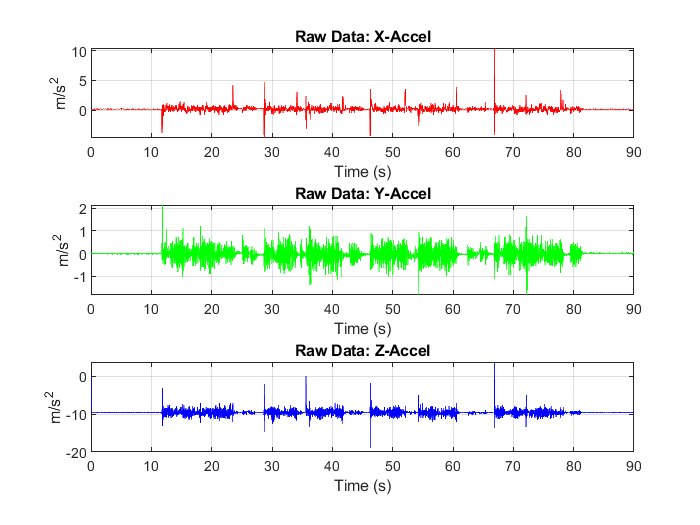

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

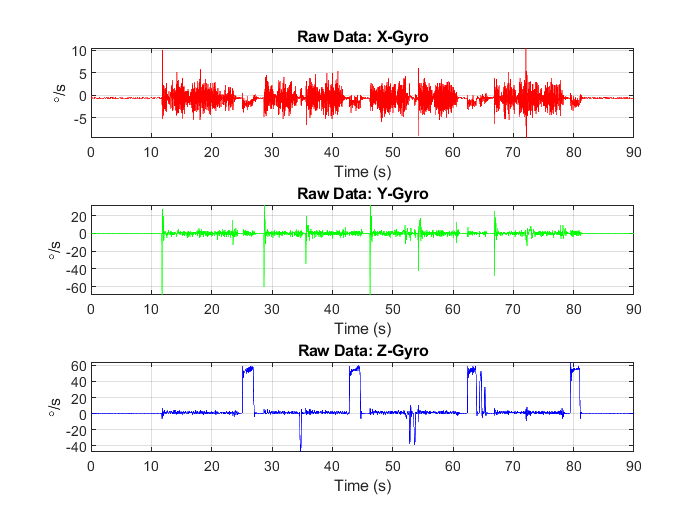

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

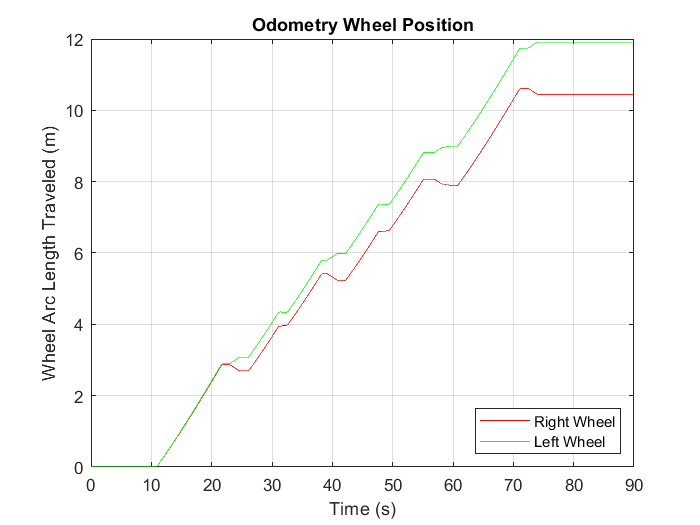

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

   
% Pre-Allocate
[kinect_samples, ~] = size(depth);
numPoints = 5000;
xyz = zeros(3, numPoints, kinect_samples);

% Convert to XYZ with down-sampling
tic
for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz(depth, numPoints, k);
end
toc

Elapsed time is 6.008836 seconds.


## Depth Camera Animation

% % Show Animation
% for k = 2 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% % Verify Good Floor Data
% test_frame = 22;
% plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
% % Pitch of two Example Points
% atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi
% % Accomplish Crude Prediction of "Ground Truth" Pitch Values
% pitch = zeros(1, num_frames);
% for n = 2 : num_frames
%     
%     % Grab and Average All Points between x = 0.5 & x = 0.6
%     xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
%     xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
%     
%     % Grab and Average All Points between x = 0.9 & x = 0.1
%     xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
%     xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
%     
%     pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
%     
% end
% 
% % Plot "Ground Truth" Estimate of Pitch
% plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
% title('"Ground Truth" Pitch Guesses')
% xlabel('Frames')
% xlim([2 num_frames])
% ylabel('Pitch (\circ)')
% grid on

## Shift Wall and Floor Point Clouds to the Origin

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
for n = 2 : num_frames
    x_max = max(xyz_wall{n}(1,:));
    x_min = min(xyz_wall{n}(1,:));
    x_shift = x_min + ((x_max - x_min)/2);
    xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.316073 seconds.


Begin Processing Frame #3

Elapsed time is 1.293148 seconds.


Begin Processing Frame #4

Elapsed time is 1.282072 seconds.


Begin Processing Frame #5

Elapsed time is 1.293404 seconds.


Begin Processing Frame #6

Elapsed time is 1.304028 seconds.


Begin Processing Frame #7

Elapsed time is 1.303273 seconds.


Begin Processing Frame #8

Elapsed time is 1.286227 seconds.


Begin Processing Frame #9

Elapsed time is 1.281170 seconds.


Begin Processing Frame #10

Elapsed time is 1.297496 seconds.


Begin Processing Frame #11

Elapsed time is 1.290759 seconds.


Begin Processing Frame #12

Elapsed time is 1.293798 seconds.


Begin Processing Frame #13

Elapsed time is 1.280639 seconds.


Begin Processing Frame #14

Elapsed time is 1.295284 seconds.


Begin Processing Frame #15

Elapsed time is 1.304595 seconds.


Begin Processing Frame #16

Elapsed time is 1.066554 seconds.


Begin Processing Frame #17

Elapsed time is 1.022405 seconds.


Begin Processing Frame #18

Elapsed time is 1.018662 seconds.


Begin Processing Frame #19

Elapsed time is 1.044389 seconds.


Begin Processing Frame #20

Elapsed time is 0.990037 seconds.


Begin Processing Frame #21

Elapsed time is 0.919305 seconds.


Begin Processing Frame #22

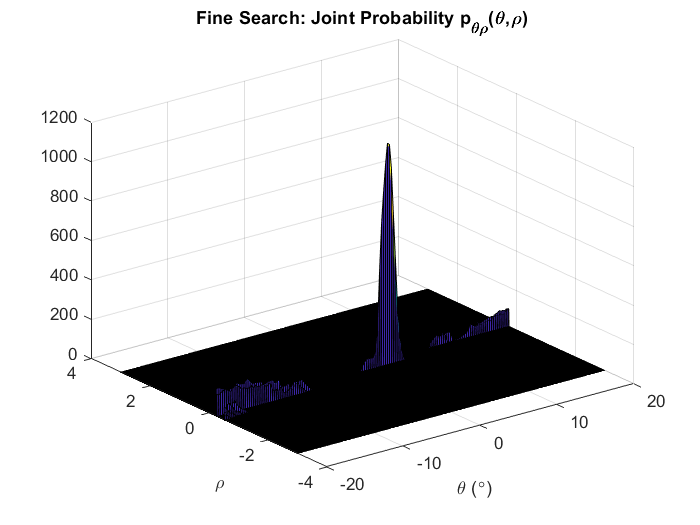

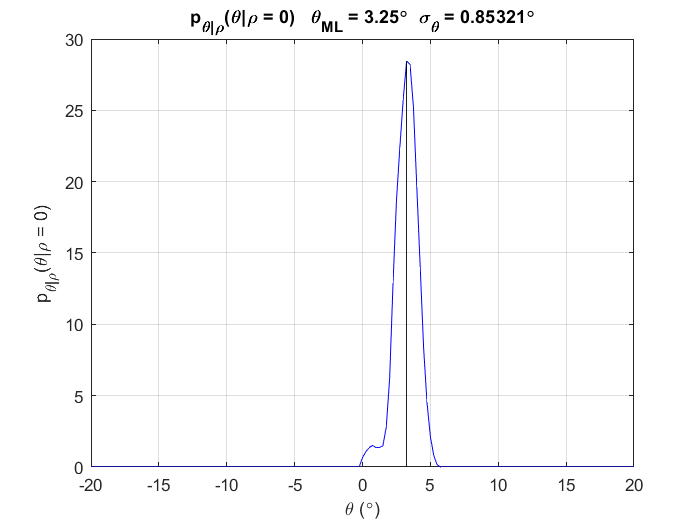

Elapsed time is 1.115777 seconds.


Begin Processing Frame #23

Elapsed time is 0.879823 seconds.


Begin Processing Frame #24

Elapsed time is 0.783693 seconds.


Begin Processing Frame #25

Elapsed time is 0.809291 seconds.


Begin Processing Frame #26

Elapsed time is 1.037781 seconds.


Begin Processing Frame #27

Elapsed time is 1.322937 seconds.


Begin Processing Frame #28

Elapsed time is 1.330777 seconds.


Begin Processing Frame #29

Elapsed time is 1.327662 seconds.


Begin Processing Frame #30

Elapsed time is 1.294678 seconds.


Begin Processing Frame #31

Elapsed time is 1.087413 seconds.


Begin Processing Frame #32

Elapsed time is 1.011294 seconds.


Begin Processing Frame #33

Elapsed time is 0.996205 seconds.


Begin Processing Frame #34

Elapsed time is 0.957679 seconds.


Begin Processing Frame #35

Elapsed time is 1.006773 seconds.


Begin Processing Frame #36

Elapsed time is 1.000450 seconds.


Begin Processing Frame #37

Elapsed time is 0.959714 seconds.


Begin Processing Frame #38

Elapsed time is 0.935200 seconds.


Begin Processing Frame #39

Elapsed time is 0.978182 seconds.


Begin Processing Frame #40

Elapsed time is 0.875008 seconds.


Begin Processing Frame #41

Elapsed time is 0.790661 seconds.


Begin Processing Frame #42

Elapsed time is 0.904868 seconds.


Begin Processing Frame #43

Elapsed time is 1.337671 seconds.


Begin Processing Frame #44

Elapsed time is 1.341137 seconds.


Begin Processing Frame #45

Elapsed time is 1.323991 seconds.


Begin Processing Frame #46

Elapsed time is 1.362510 seconds.


Begin Processing Frame #47

Elapsed time is 1.127963 seconds.


Begin Processing Frame #48

Elapsed time is 1.047230 seconds.


Begin Processing Frame #49

Elapsed time is 1.017671 seconds.


Begin Processing Frame #50

Elapsed time is 1.004471 seconds.


Begin Processing Frame #51

Elapsed time is 1.020492 seconds.


Begin Processing Frame #52

Elapsed time is 1.036266 seconds.


Begin Processing Frame #53

Elapsed time is 0.966921 seconds.


Begin Processing Frame #54

Elapsed time is 0.923020 seconds.


Begin Processing Frame #55

Elapsed time is 0.897623 seconds.


Begin Processing Frame #56

Elapsed time is 0.892800 seconds.


Begin Processing Frame #57

Elapsed time is 0.799844 seconds.


Begin Processing Frame #58

Elapsed time is 0.648154 seconds.


Begin Processing Frame #59

Elapsed time is 0.770449 seconds.


Begin Processing Frame #60

Elapsed time is 1.040182 seconds.


Begin Processing Frame #61

Elapsed time is 1.260468 seconds.


Begin Processing Frame #62

Elapsed time is 1.301095 seconds.


Begin Processing Frame #63

Elapsed time is 1.263784 seconds.


Begin Processing Frame #64

Elapsed time is 1.287702 seconds.


Begin Processing Frame #65

Elapsed time is 1.056581 seconds.


Begin Processing Frame #66

Elapsed time is 1.046425 seconds.


Begin Processing Frame #67

Elapsed time is 0.995692 seconds.


Begin Processing Frame #68

Elapsed time is 0.895050 seconds.


Begin Processing Frame #69

Elapsed time is 0.992529 seconds.


Begin Processing Frame #70

Elapsed time is 0.933623 seconds.


Begin Processing Frame #71

Elapsed time is 0.898756 seconds.


Begin Processing Frame #72

Elapsed time is 0.907687 seconds.


Begin Processing Frame #73

Elapsed time is 0.751350 seconds.


Begin Processing Frame #74

Elapsed time is 0.643828 seconds.


Begin Processing Frame #75

Elapsed time is 0.823919 seconds.


Begin Processing Frame #76

Elapsed time is 1.296596 seconds.


Begin Processing Frame #77

Elapsed time is 1.289484 seconds.


Begin Processing Frame #78

Elapsed time is 1.270683 seconds.


Begin Processing Frame #79

Elapsed time is 1.295394 seconds.


Begin Processing Frame #80

Elapsed time is 1.290383 seconds.


Begin Processing Frame #81

Elapsed time is 1.300282 seconds.


Begin Processing Frame #82

Elapsed time is 1.278828 seconds.


Begin Processing Frame #83

Elapsed time is 1.288911 seconds.


Begin Processing Frame #84

Elapsed time is 1.282932 seconds.


Begin Processing Frame #85

Elapsed time is 1.297690 seconds.


Begin Processing Frame #86

Elapsed time is 1.293151 seconds.


Begin Processing Frame #87

Elapsed time is 1.282206 seconds.


Begin Processing Frame #88

Elapsed time is 1.281046 seconds.


Begin Processing Frame #89

Elapsed time is 1.285496 seconds.


Begin Processing Frame #90

Elapsed time is 1.281543 seconds.


Begin Processing Frame #91

Elapsed time is 1.301352 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

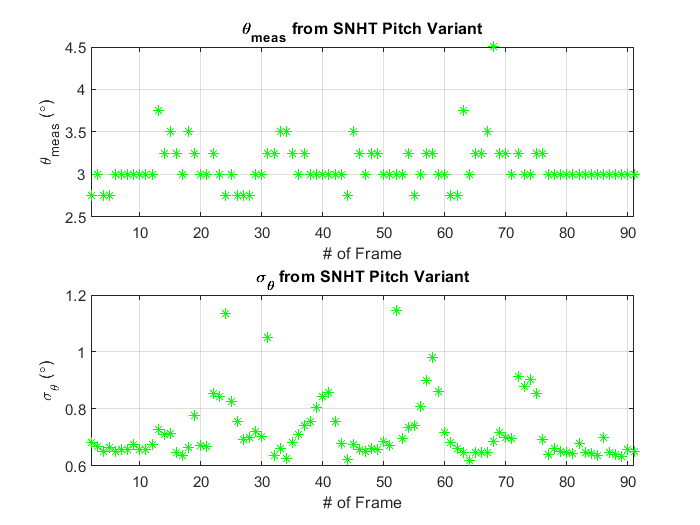

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 0.866806 seconds.


Begin Processing Frame #3

Elapsed time is 0.809650 seconds.


Begin Processing Frame #4

Elapsed time is 0.826062 seconds.


Begin Processing Frame #5

Elapsed time is 0.696591 seconds.


Begin Processing Frame #6

Elapsed time is 0.792728 seconds.


Begin Processing Frame #7

Elapsed time is 0.687454 seconds.


Begin Processing Frame #8

Elapsed time is 0.766104 seconds.


Begin Processing Frame #9

Elapsed time is 0.794225 seconds.


Begin Processing Frame #10

Elapsed time is 0.738565 seconds.


Begin Processing Frame #11

Elapsed time is 0.722958 seconds.


Begin Processing Frame #12

Elapsed time is 0.756304 seconds.


Begin Processing Frame #13

Elapsed time is 0.651158 seconds.


Begin Processing Frame #14

Elapsed time is 0.654266 seconds.


Begin Processing Frame #15

Elapsed time is 0.563537 seconds.


Begin Processing Frame #16

Elapsed time is 1.702066 seconds.


Begin Processing Frame #17

Elapsed time is 1.942504 seconds.


Begin Processing Frame #18

Elapsed time is 2.096916 seconds.


Begin Processing Frame #19

Elapsed time is 2.123752 seconds.


Begin Processing Frame #20

Elapsed time is 2.449278 seconds.


Begin Processing Frame #21

Elapsed time is 2.772092 seconds.


Begin Processing Frame #22

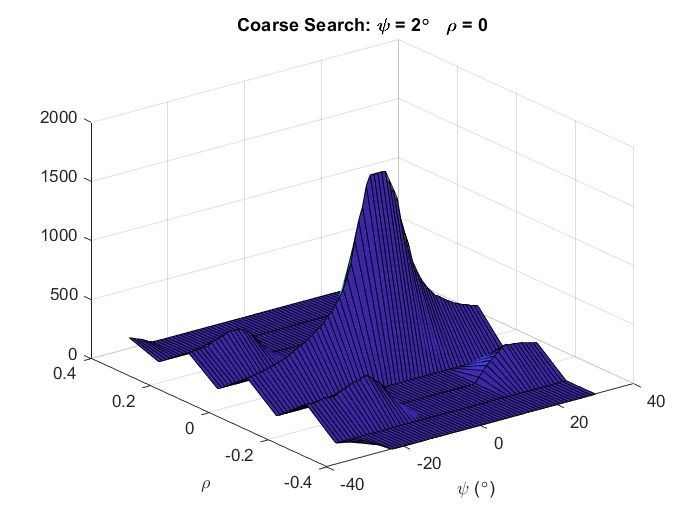

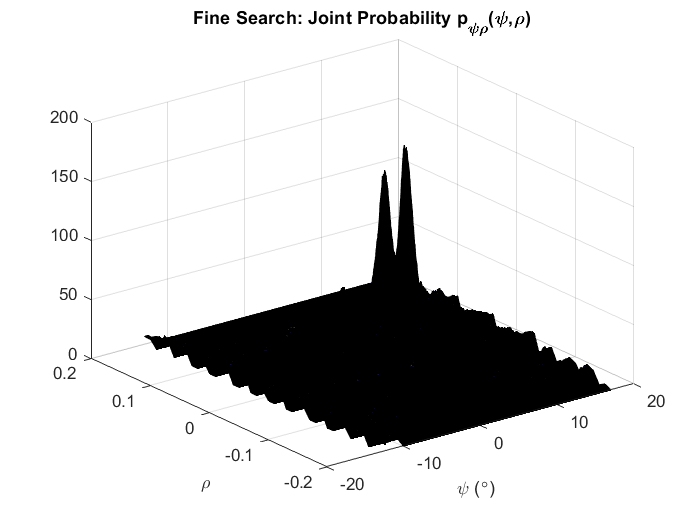

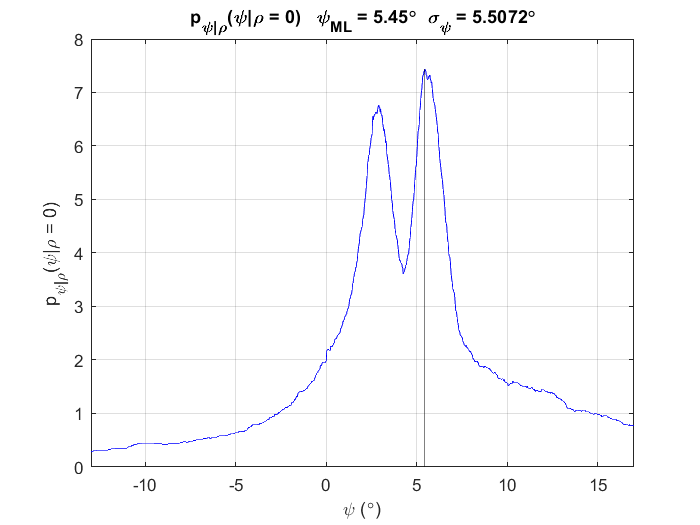

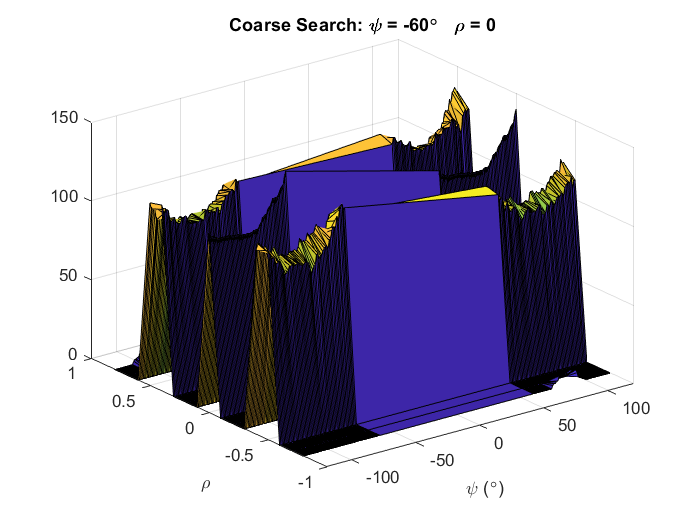

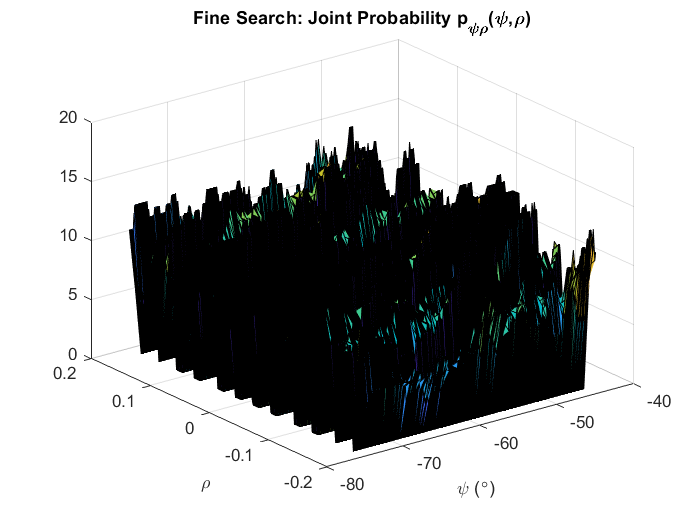

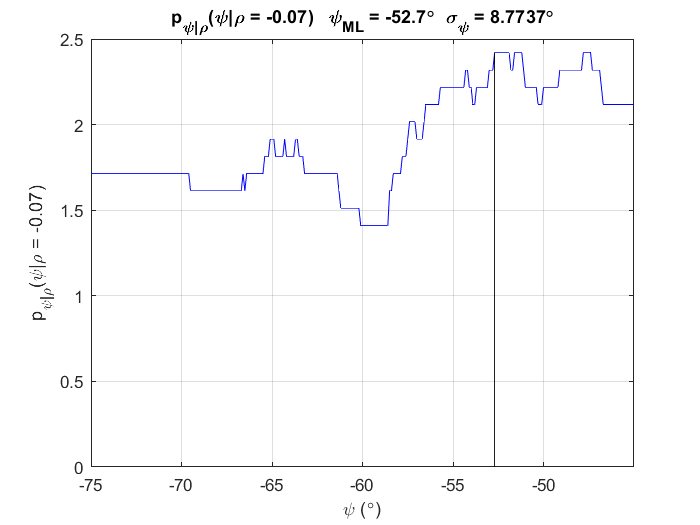

Elapsed time is 3.484297 seconds.


Begin Processing Frame #23

Elapsed time is 3.563008 seconds.


Begin Processing Frame #24

Elapsed time is 4.218657 seconds.


Begin Processing Frame #25

Elapsed time is 4.116167 seconds.


Begin Processing Frame #26

Elapsed time is 2.680799 seconds.


Begin Processing Frame #27

Elapsed time is 0.460247 seconds.


Begin Processing Frame #28

Elapsed time is 0.457350 seconds.


Begin Processing Frame #29

Elapsed time is 0.329598 seconds.


Begin Processing Frame #30

Elapsed time is 0.284290 seconds.


Begin Processing Frame #31

Elapsed time is 1.460345 seconds.


Begin Processing Frame #32

Elapsed time is 1.818245 seconds.


Begin Processing Frame #33

Elapsed time is 2.016503 seconds.


Begin Processing Frame #34

Elapsed time is 2.016616 seconds.


Begin Processing Frame #35

Elapsed time is 2.021011 seconds.


Begin Processing Frame #36

Elapsed time is 2.128705 seconds.


Begin Processing Frame #37

Elapsed time is 2.346290 seconds.


Begin Processing Frame #38

Elapsed time is 2.604330 seconds.


Begin Processing Frame #39

Elapsed time is 3.092121 seconds.


Begin Processing Frame #40

Elapsed time is 3.690081 seconds.


Begin Processing Frame #41

Elapsed time is 4.223017 seconds.


Begin Processing Frame #42

Elapsed time is 2.966566 seconds.


Begin Processing Frame #43

Elapsed time is 0.354068 seconds.


Begin Processing Frame #44

Elapsed time is 0.383299 seconds.


Begin Processing Frame #45

Elapsed time is 0.267334 seconds.


Begin Processing Frame #46

Elapsed time is 0.201479 seconds.


Begin Processing Frame #47

Elapsed time is 1.511894 seconds.


Begin Processing Frame #48

Elapsed time is 1.851024 seconds.


Begin Processing Frame #49

Elapsed time is 1.996647 seconds.


Begin Processing Frame #50

Elapsed time is 2.430847 seconds.


Begin Processing Frame #51

Elapsed time is 2.255511 seconds.


Begin Processing Frame #52

Elapsed time is 2.102145 seconds.


Begin Processing Frame #53

Elapsed time is 2.443072 seconds.


Begin Processing Frame #54

Elapsed time is 2.711105 seconds.


Begin Processing Frame #55

Elapsed time is 3.087614 seconds.


Begin Processing Frame #56

Elapsed time is 3.422988 seconds.


Begin Processing Frame #57

Elapsed time is 4.139495 seconds.


Begin Processing Frame #58

Elapsed time is 5.110770 seconds.


Begin Processing Frame #59

Elapsed time is 4.465496 seconds.


Begin Processing Frame #60

Elapsed time is 2.645098 seconds.


Begin Processing Frame #61

Elapsed time is 0.963262 seconds.


Begin Processing Frame #62

Elapsed time is 0.776874 seconds.


Begin Processing Frame #63

Elapsed time is 0.771548 seconds.


Begin Processing Frame #64

Elapsed time is 0.662097 seconds.


Begin Processing Frame #65

Elapsed time is 1.880348 seconds.


Begin Processing Frame #66

Elapsed time is 1.948061 seconds.


Begin Processing Frame #67

Elapsed time is 2.093220 seconds.


Begin Processing Frame #68

Elapsed time is 2.154962 seconds.


Begin Processing Frame #69

Elapsed time is 2.197772 seconds.


Begin Processing Frame #70

Elapsed time is 2.493837 seconds.


Begin Processing Frame #71

Elapsed time is 2.969894 seconds.


Begin Processing Frame #72

Elapsed time is 3.444373 seconds.


Begin Processing Frame #73

Elapsed time is 4.435848 seconds.


Begin Processing Frame #74

Elapsed time is 5.151125 seconds.


Begin Processing Frame #75

Elapsed time is 4.045898 seconds.


Begin Processing Frame #76

Elapsed time is 0.650254 seconds.


Begin Processing Frame #77

Elapsed time is 0.797748 seconds.


Begin Processing Frame #78

Elapsed time is 0.773407 seconds.


Begin Processing Frame #79

Elapsed time is 0.817841 seconds.


Begin Processing Frame #80

Elapsed time is 0.709580 seconds.


Begin Processing Frame #81

Elapsed time is 0.728474 seconds.


Begin Processing Frame #82

Elapsed time is 0.854962 seconds.


Begin Processing Frame #83

Elapsed time is 0.757711 seconds.


Begin Processing Frame #84

Elapsed time is 0.766583 seconds.


Begin Processing Frame #85

Elapsed time is 0.714512 seconds.


Begin Processing Frame #86

Elapsed time is 0.779397 seconds.


Begin Processing Frame #87

Elapsed time is 0.770635 seconds.


Begin Processing Frame #88

Elapsed time is 0.861394 seconds.


Begin Processing Frame #89

Elapsed time is 0.874974 seconds.


Begin Processing Frame #90

Elapsed time is 0.825999 seconds.


Begin Processing Frame #91

Elapsed time is 0.729826 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

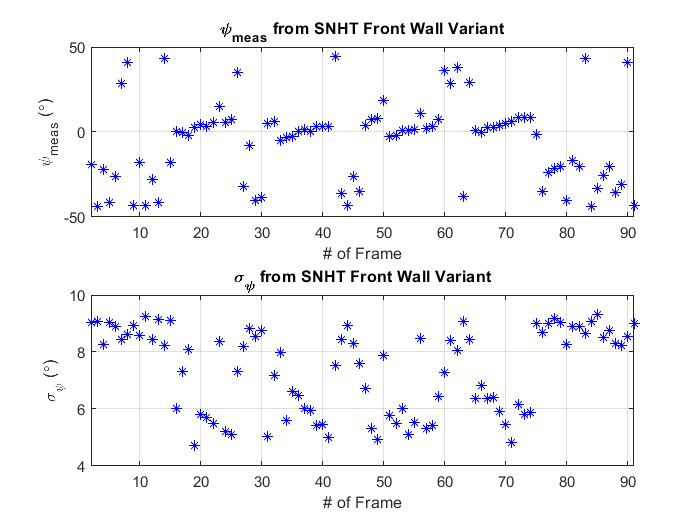

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

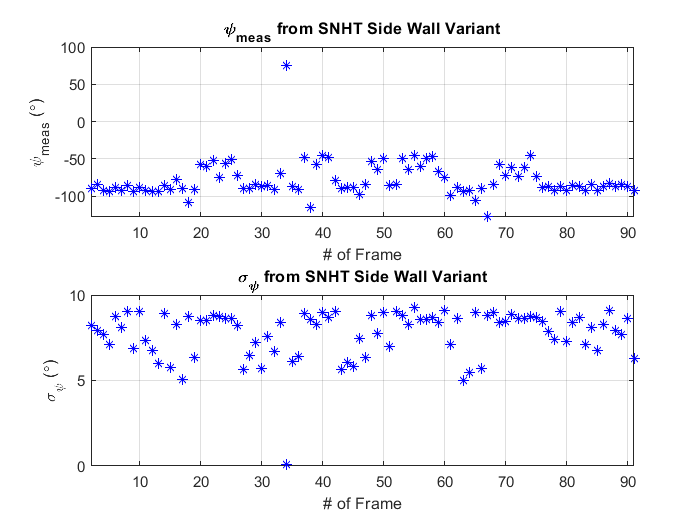

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

% Save to Structure
P.Fs = Fs;                         % Hz
P.dt = dt;                         % s
P.t = t;                           % s
P.t_end = t(end);                  % s
P.init_time = init_time;           % s
P.accel = double(accel);           % m/s^2
P.gyro = double(gyro);             % rad/s
P.odo = odo;                       % m
P.baro = 84.5*ones(1, length(t));  % kPa -- fake measurement for now!
P.theta_meas = theta_meas;         % rad
P.theta_sigmas = theta_sigmas;     % rad
P.psi_fw_meas = psi_fw_meas;       % rad
P.psi_fw_sigmas = psi_fw_sigmas;   % rad
P.psi_sw_meas = psi_sw_meas;       % rad
P.psi_sw_sigmas = psi_sw_sigmas;   % rad

save("SBT_CW.mat", 'P')
P

P = struct with fields:
               Fs: 50
               dt: 0.0200
                t: [1×4501 double]
            t_end: 90
        init_time: 12
            accel: [3×4501 double]
             gyro: [3×4501 double]
              odo: [2×4501 double]
             baro: [1×4501 double]
       theta_meas: [1×91 double]
     theta_sigmas: [1×91 double]
      psi_fw_meas: [1×91 double]
    psi_fw_sigmas: [1×91 double]
      psi_sw_meas: [1×91 double]
    psi_sw_sigmas: [1×91 double]


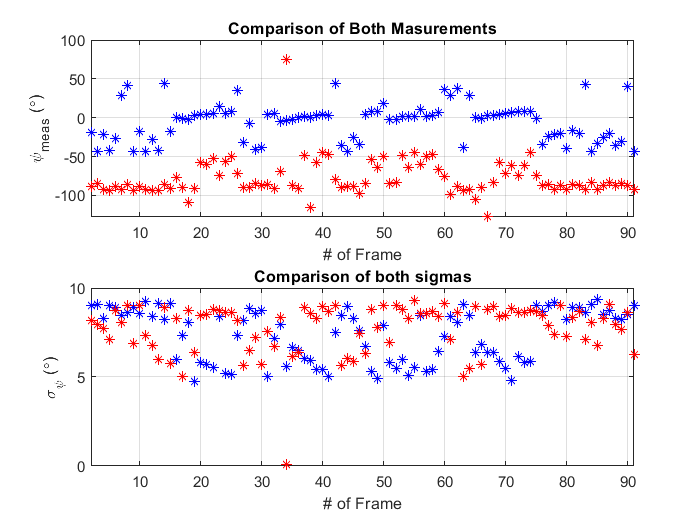

% Quick Test
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*', 1:num_frames, psi_sw_meas * 180/pi, 'r*')
title('Comparison of Both Masurements')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*', 1:num_frames, psi_sw_sigmas * 180/pi, 'r*')
title('Comparison of both sigmas')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on